clear

## Load data from Excel file, see section 2.2 in 03IntroduktioniMatlab.pdf

Data = readtable("timeSeries.xlsx", ...
                        "Sheet", "Problem 1 and 2", ...
                        "DataRange","B3:G1512");
Data.Properties.VariableNames = ["Date", "BAC", "C", "GS", "MS", "WFC"];
BankStockstimeSeries = flip(Data);

Task3Table = readtable("timeSeries.xlsx", ...
                        "Sheet", "Problem 3", ...
                        "DataRange","B4:E3429");
Task3Table.Properties.VariableNames = ["Date", "SP500", "VIX", "InterestRate"];

Task3TableOptions = readtable("timeSeries.xlsx", ...
                        "Sheet", "Problem 3", ...
                        "DataRange","G4:J6");
Task3TableOptions.Properties.VariableNames = ["KTType", "IVBid", "IVAsk", "Holdings"];

## Task 1: Bank Stocks Data Analysis

% 1. Display the first few rows of the dataset
disp("--- First 5 rows of Bank Stocks Data (Chronological) ---")

--- First 5 rows of Bank Stocks Data (Chronological) ---


head(BankStockstimeSeries, 5)

       Date         BAC       C        GS       MS       WFC 
    ___________    _____    _____    ______    _____    _____

    02-Jan-2019    24.96    53.53    172.03     40.4    46.94
    03-Jan-2019    24.56    52.56    169.51    39.68    46.57
    04-Jan-2019    25.58    55.13    175.05     41.3    47.95
    07-Jan-2019    25.56    55.61    176.02    41.71    47.64
    08-Jan-2019    25.51    55.46    175.37    41.45    47.54



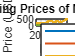


% 2. Plot the time series of the 5 bank stocks
figure;
plot(BankStockstimeSeries.Date, BankStockstimeSeries.BAC, 'LineWidth', 1.5); hold on;
plot(BankStockstimeSeries.Date, BankStockstimeSeries.C, 'LineWidth', 1.5);
plot(BankStockstimeSeries.Date, BankStockstimeSeries.GS, 'LineWidth', 1.5);
plot(BankStockstimeSeries.Date, BankStockstimeSeries.MS, 'LineWidth', 1.5);
plot(BankStockstimeSeries.Date, BankStockstimeSeries.WFC, 'LineWidth', 1.5);
hold off;

% Format the graph
title('Daily Closing Prices of Major US Banks');
xlabel('Date');
ylabel('Price (USD)');
legend('BAC', 'C', 'GS', 'MS', 'WFC', 'Location', 'northwest');
grid on;

## Task 1a VaR and ES

% Extract prices and calculate daily relative returns
prices = BankStockstimeSeries{:, 2:end}; % 2nd to right most column
returns = diff(prices) ./ prices(1:end-1, :); % First row to the second to last
[n_days, n_assets] = size(returns);

% Equally weighted portfolio
weights = repmat(1/n_assets, n_assets, 1);

% =========================================================================
% Task 1(a): VaR and ES (Variance-Covariance Method)
% =========================================================================

% Portfolio mean and standard deviation
mu = mean(returns)'; % Average daily return
Sigma = cov(returns);
mu_portfolio = weights' * mu;
sigma_portfolio = sqrt(weights' * Sigma * weights);

% Confidence levels
c_levels = [0.95, 0.99];
z_scores = norminv(c_levels);

% Calculate relative VaR and ES (expressed in decimals first)

% The cutoff point for the worst $1-\alpha$ cases.
VaR_VCov = -mu_portfolio + sigma_portfolio .* z_scores;
%The average loss beyond the VaR threshold.
ES_VCov = -mu_portfolio + sigma_portfolio .* (normpdf(z_scores) ./ (1 - c_levels));

output.Task1.VCov.VaR = VaR_VCov * 100;
output.Task1.VCov.ES = ES_VCov * 100;


## Task 1b Monte Carlo Simulation (GARCH + Student-t Copula)

garch_parameters = zeros(3, n_assets); % omega, alpha, beta
std_residuals = zeros(n_days, n_assets);
sigma_T_plus_1 = zeros(1, n_assets);

% Optimization options
options = optimoptions('fmincon', 'Display', 'off', 'Algorithm', 'sqp');

% 1. Estimate GARCH(1,1) for each stock using custom MLE
for i = 1:n_assets
    current_asset_returns = returns(:, i);
    longterm_variance = var(current_asset_returns);
    
    alpha_start_value = 0.10;
    beta_start_value  = 0.85;
    omega_start_value = longterm_variance * (1 - alpha_start_value - beta_start_value); % omega = V_L * gamma = ...
    
    initial_parameters_garch = [max(omega_start_value, 1e-9), alpha_start_value, beta_start_value];
    
    % Inequality constraints: Alpha + Beta <= 0.999
    alpha_ineq = [0 1 1]; 
    beta_ineq = 0.999;
    lower_bounds = [1e-9, 0.001, 0.001];
    
    % Optimize using fmincon --> Finds what parameters give the minimum
    [optimal_params_garch, ~] = fmincon(@(p) garch_loglik(p, current_asset_returns), ...
                                                initial_parameters_garch, alpha_ineq, beta_ineq, [], [], lower_bounds, [], [], options);
    % Store parameters
    garch_parameters(1, i) = optimal_params_garch(1); % omega
    garch_parameters(2, i) = optimal_params_garch(2); % alpha
    garch_parameters(3, i) = optimal_params_garch(3); % beta
    
    % Calculate volatilty based on the optimal garch parameters
    [~, garch_estimated_variance] = garch_loglik(optimal_params_garch, current_asset_returns);
    % Calculate the resdiuals (the remaning volatilty when the garch volatiltiy is removed)
    std_residuals(:, i) = current_asset_returns ./ sqrt(garch_estimated_variance);
    
    % Forecast volatility for t = T+1 using the normal GARCH(1,1) formula
    sigma_T_plus_1(i) = sqrt(optimal_params_garch(1) + optimal_params_garch(2) * current_asset_returns(end)^2 + optimal_params_garch(3) * garch_estimated_variance(end));
end

% 2. Copula transformation (Normal CDF)
% The residuals contain the residing volatility after the volatility clustering was removed using GARCH above
% normdcdf applies the standard normal cdf to the residuals
U = normcdf(std_residuals); % U = Uniform probabilities between 0 and 1
U(U >= 1) = 1 - 1e-6; U(U <= 0) = 1e-6; % Prevent exact 0 or 1 for stability

% 3. Fit Student-t copula with Gaussian fallback
try
    [Rho, nu] = copulafit('t', U); % Rho is the correlation matrix
    best_copula_name = 't'; % "nu" = df = degrees of freedom
catch
    Rho = copulafit('Gaussian', U);
    nu = 0; % Dummy value for Gaussian fallback
    best_copula_name = 'Gaussian';
end

% 4. Simulate 1000 samples
n_sim = 1000;
rng(1); % Random number seed for reproducibility

if strcmp(best_copula_name, 't')
    U_sim = copularnd('t', Rho, nu, n_sim);
else
    U_sim = copularnd('Gaussian', Rho, n_sim);
end
% Thanks to the copula, these random numbers respect the historical correlation structure of the banks.

% Transform back to residuals using Normal inverse
sim_residuals = norminv(U_sim);

% 5. Calculate simulated returns and portfolio losses
sim_returns = sim_residuals .* repmat(sigma_T_plus_1, n_sim, 1);
sim_port_returns = sim_returns * weights;
sim_loss = -sim_port_returns;

% Calculating VaR is easy --> sort the 1000 simulated losses from best to worst
% and look at the 95th and 99th percentiles.
VaR_MC = [prctile(sim_loss, 95), prctile(sim_loss, 99)];
% ES is found by finding all sim losses that are worse that the VaR
ES_MC = [mean(sim_loss(sim_loss >= VaR_MC(1))), mean(sim_loss(sim_loss >= VaR_MC(2)))];

output.Task1.MC.GARCH = garch_parameters;
output.Task1.MC.nu = nu;
output.Task1.MC.rho = Rho;
output.Task1.MC.VaR = VaR_MC * 100;
output.Task1.MC.ES = ES_MC * 100;


## Task 1(c): Extreme Value Theory (EVT)

Instead of trying to model the entire distribution of daily returns (which are mostly normal days), EVT throws away the center of the data and strictly models the "tail" --> the "**extreme"** worst days

hist_port_returns = returns * weights;
Loss_hist = -hist_port_returns * 100;

% --- Subtask i: EVT on Entire Data Set ---
threshold = 95; % 95th percentile of historical losses

prctile_start_value = prctile(Loss_hist, threshold); 
excess_of_exceeded_values = Loss_hist(Loss_hist > prctile_start_value) - prctile_start_value;

params_entire = gpfit(excess_of_exceeded_values); % Generalized Pareto Distribution
xi_ent = params_entire(1); % The shape parameter, how "fat" the extreme tail is.
beta_ent = params_entire(2); % The scale parameter, dispersion of the extreme losses.

n_ent = length(Loss_hist);
n_u_ent = length(excess_of_exceeded_values);

c_evt = 0.99; % 99% VaR
% Peaks Over Threshold (POT) formula
VaR_EVT_ent = prctile_start_value + (beta_ent / xi_ent) * (((n_ent / n_u_ent) * (1 - c_evt))^(-xi_ent) - 1);
ES_EVT_ent = (VaR_EVT_ent + (beta_ent * 100) - (xi_ent * prctile_start_value)) / (1 - xi_ent);

% --- Subtask ii: EVT on Volatile Period (Approx 500 obs) ---
% Searching for the most volatile 500 day period
roll_var = zeros(n_ent - 499, 1);
for i = 1:(n_ent - 499)
    roll_var(i) = var(Loss_hist(i:i+499));
end
[~, max_idx] = max(roll_var); % starting index of the most volatile 500 day window
volatile_window = Loss_hist(max_idx:max_idx + 499);

% Same as above, Calculates the VaR and ES using the POT formula
u_vol = prctile(volatile_window, 95);
exceedances_vol = volatile_window(volatile_window > u_vol) - u_vol;

params_vol = gpfit(exceedances_vol);
xi_vol = params_vol(1);
beta_vol = params_vol(2);

n_vol = length(volatile_window);
nu_vol = length(exceedances_vol);

VaR_EVT_vol = u_vol + (beta_vol / xi_vol) * (((n_vol / nu_vol) * (1 - c_evt))^(-xi_vol) - 1);
ES_EVT_vol = (VaR_EVT_vol + beta_vol - xi_vol * u_vol) / (1 - xi_vol);

output.Task1.EVT.xibeta = [xi_ent, beta_ent; xi_vol, beta_vol]; 
output.Task1.EVT.VaR = [VaR_EVT_ent, VaR_EVT_vol] ;
output.Task1.EVT.ES = [ES_EVT_ent, ES_EVT_vol];


## Task 2: Historical Simulation (Rolling Window) and Backtesting

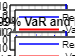

Start_day = 501;
window_size = 500;
Last_day = n_days;
n_days = Last_day - Start_day + 1;

% Initialize storage for VaR, ES, and Realized Returns
VaR_95 = zeros(n_days, 1);
VaR_99 = zeros(n_days, 1);
ES_95  = zeros(n_days, 1);
ES_99  = zeros(n_days, 1);
actual_porfolio_ret = zeros(n_days, 1);

% Initialize weights: Equally weighted at t = 500
weigts_prev = repmat(1/n_assets, 1, n_assets);

% Loop through time steps t = 501 to T
for t = Start_day:Last_day
    idx = t - Start_day + 1;
    
    % 1. Get realized returns for day t and historical window
    todays_return = returns(t, :); % All remaning days
    r_hist = returns(t-window_size : t-1, :); % The previous 500 days
    
    % 2. Calculate scenarios of portfolio returns based on weights at t-1
    portfolio_scenarios = r_hist * weigts_prev';
    losses = -portfolio_scenarios;
    
    % 3. Calculate VaR and ES
    VaR_95(idx) = prctile(losses, 95);
    VaR_99(idx) = prctile(losses, 99);
    ES_95(idx)  = mean(losses(losses >= VaR_95(idx)));
    ES_99(idx)  = mean(losses(losses >= VaR_99(idx)));
    
    % 4. Realized portfolio return at time t
    Portfolio_return_today = todays_return * weigts_prev'; % Todays actual return
    actual_porfolio_ret(idx) = Portfolio_return_today;
    
    % 5. Update weights for the next day
    % If a single stock grows more than the portfolio its weight is increased for the next day
    w_current = weigts_prev .* (1 + todays_return) / (1 + Portfolio_return_today); 
    weigts_prev = w_current;
end

% =========================================================================
% Backtesting: 95% VaR
% =========================================================================

% 1. Determine Violation Indicators (1 if loss > VaR, 0 otherwise)
I_t = (-actual_porfolio_ret) > VaR_95;

% --- Task 2(a): Unconditional Coverage Test (Violation Rate) ---
X_T = sum(I_t); % Number of violations where the losses exceeded the calculated VaR of 95%
N = length(I_t);
p_obs = X_T / N; % The observed failure rate (When the portfolio losses exceed VaR 95%)
p_expected = 0.05; % p-value

% Z-test statistic for binomial proportions
% Bad luck or statistically significant?
Z_stat = (X_T - N * p_expected) / sqrt(N * p_expected * (1 - p_expected));
crit_val_Z = 1.96; % 5% significance level (two-sided)

% --- Task 2(b): Christoffersen's Test for Serial Dependence ---
% Count transitions
I_t_1 = I_t(1:end-1); % Yesterday
I_t_0 = I_t(2:end); % Today

% Counting the states, how many time does each sequence happen
n00 = sum(I_t_1 == 0 & I_t_0 == 0); % Today 0 AND yesterday 0
n01 = sum(I_t_1 == 0 & I_t_0 == 1); % Today 0 AND yesterday 1
n10 = sum(I_t_1 == 1 & I_t_0 == 0); % Today 1 AND yesterday 0 
n11 = sum(I_t_1 == 1 & I_t_0 == 1); % Today 1 AND yesterday 1

% Transition probabilities
probability_of_exceeding = (n01 + n11) / (n00 + n01 + n10 + n11);
pi01 = n01 / (n00 + n01); % Probability of violation today given that yesterday was safe

if (n10 + n11) > 0
    pi11 = n11 / (n10 + n11); % Probability of violation today given that yesterday was also a violation
else
    pi11 = 0;
end

% Log-likelihoods (with protections against log(0))
term00 = 0; if n00 > 0, term00 = n00 * log(1 - pi01); end
term01 = 0; if n01 > 0, term01 = n01 * log(pi01); end
term10 = 0; if n10 > 0, term10 = n10 * log(1 - pi11); end
term11 = 0; if n11 > 0, term11 = n11 * log(pi11); end

% LogL0 is the likelihood of your data if violations are completely independent
logL0 = (n00 + n10) * log(1 - probability_of_exceeding) + (n01 + n11) * log(probability_of_exceeding);
% LogL1 is the likelihood of your data if today's outcome depends on yesterday's.
logL1 = term00 + term01 + term10 + term11;

% Likelihood Ratio Statistic
% If LR_ind > 3.84, it means violations are clustering together, and your model fails the independence test.
LR_ind = -2 * (logL0 - logL1);
crit_val_LR = 3.84; % Chi-square 1 df at 5% significance

% =========================================================================
% Assign Output Objects
% =========================================================================

output.Task2.ViolationRate = p_obs;
output.Task2.TransitionN = [n00, n01, n10, n11]; % [n00, n01, n10, n11]
output.Task2.TestStats = [Z_stat, LR_ind];       % [Violation Z-test, Christoffersen LR]
output.Task2.CritialVal = [crit_val_Z, crit_val_LR]; 

% =========================================================================
% Plotting VaR, ES, and Realized Returns
% =========================================================================

dates_eval = BankStockstimeSeries.Date(Start_day+1:end); % Match index size with returns

figure;
% 95% Confidence Level Plot
subplot(2, 1, 1);
plot(dates_eval, actual_porfolio_ret * 100, 'b', 'LineWidth', 1); hold on;
plot(dates_eval, -VaR_95 * 100, 'r', 'LineWidth', 1.5);
plot(dates_eval, -ES_95 * 100, 'm', 'LineWidth', 1.5);
title('Historical Simulation: 95% VaR and ES vs Realized Returns');
ylabel('Return (%)');
legend('Realized Return', '-VaR 95%', '-ES 95%', 'Location', 'southwest');
grid on; hold off;

% 99% Confidence Level Plot
subplot(2, 1, 2);
plot(dates_eval, actual_porfolio_ret * 100, 'b', 'LineWidth', 1); hold on;
plot(dates_eval, -VaR_99 * 100, 'r', 'LineWidth', 1.5);
plot(dates_eval, -ES_99 * 100, 'm', 'LineWidth', 1.5);
title('Historical Simulation: 99% VaR and ES vs Realized Returns');
xlabel('Date');
ylabel('Return (%)');
legend('Realized Return', '-VaR 99%', '-ES 99%', 'Location', 'southwest');
grid on; hold off;

## Task 3: Market Data and Options Portfolio Data analysis


% 1. Display the first few rows of the market data and the portfolio
disp("--- First 5 rows of Macro Market Data (TS3) ---")

--- First 5 rows of Macro Market Data (TS3) ---


head(Task3Table, 5)

       Date        SP500      VIX     InterestRate
    ___________    ______    _____    ____________

    10-Jan-2022    4670.3     19.4      0.23829   
    07-Jan-2022      4677    18.76      0.23614   
    06-Jan-2022    4696.1    19.61      0.23129   
    05-Jan-2022    4700.6    19.73      0.22557   
    04-Jan-2022    4793.5    16.91        0.216   




disp("--- Options Portfolio Holdings (Tab4) ---")

--- Options Portfolio Holdings (Tab4) ---


head(Task3TableOptions) % Tab4 only has 3 rows, so this displays the whole table

          KTType           IVBid    IVAsk    Holdings
    ___________________    _____    _____    ________

    {'4700,Mar22,Call'}     15.7    15.84     10000  
    {'4600,Mar22,Put' }    18.23    18.33     10000  
    {'4750,Apr22,Call'}    16.19     16.3     20000  



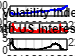


% 2. Plot the time series of the Market Data
figure;

% Top graph: S&P 500
subplot(3, 1, 1);
plot(Task3Table.Date, Task3Table.SP500, 'b', 'LineWidth', 1.5);
title('S&P 500 Index');
ylabel('Index Level');
grid on;

% Middle graph: VIX
subplot(3, 1, 2);
plot(Task3Table.Date, Task3Table.VIX, 'r', 'LineWidth', 1.5);
title('CBOE Volatility Index (VIX)');
ylabel('Volatility');
grid on;

% Bottom graph: 3-Month Interest Rate
subplot(3, 1, 3);
plot(Task3Table.Date, Task3Table.InterestRate, 'k', 'LineWidth', 1.5);
title('3-Month US Interest Rate');
xlabel('Date');
ylabel('Rate');
grid on;

## Task 3: Risk factor mapping

% 1. Calculate Risk Factor Changes 
% Note: The assignment specifies changes in level for S&P500, and changes 
% in percentage points for VIX and Interest Rates. 
dx_S = diff(flipud(Task3Table.SP500));         % Level change
dx_V = diff(flipud(Task3Table.VIX)) / 100;           % Level change (Percentage points)
dx_R = diff(flipud(Task3Table.InterestRate)) / 100;  % Level change (Percentage points)

% Combine risk factor changes into a matrix and compute the covariance matrix
DeltaXi = [dx_S, dx_V, dx_R];
disp("--- Covariance Matrix ---")

--- Covariance Matrix ---


CovDeltaXi = cov(DeltaXi) % How SP500, VIX, r_f move together

CovDeltaXi =   652.4095   -0.4149    0.0000
   -0.4149    0.0004    0.0000
    0.0000    0.0000    0.0000



% 2. Extract current market conditions (t = T)
S0 = Task3Table.SP500(1);
r0 = Task3Table.InterestRate(1) / 100; % Ensure rate is decimal for BSM
q  = 0.05; % Continuous dividend rate (5%)

% 3. Extract Options Portfolio details
% Mid price of the implied volatility
IV_mid = ((Task3TableOptions.IVBid + Task3TableOptions.IVAsk) / 2) / 100; % Percentages
holdings = Task3TableOptions.Holdings;
n_options = length(holdings);

% Strike (K), Time to Maturity (T), and Option Type
K = [4700; 4600; 4750];      % <-- Actual strikes from KTType
T = [67/365; 67/365; 94/365];% <-- Maturities in years from Jan 10, 2022
isCall = [true; false; true];% <-- Actual types (true for Call, false for Put)
% ----------------------------------------------------------------------

% 4. Calculate the Gradient Vectors (G matrix) using BSM Greeks
% Rows: Risk factors (S, V, R)
% Columns: Options (1, 2, 3)
G_mat = zeros(3, n_options);

% Delta (blsdelta): Sensitivity to the S&P 500 price.
% Vega (blsvega): Sensitivity to Implied Volatility (VIX
% Rho (blsrho): Sensitivity to Interest Rates.

for i = 1:n_options
    % Calculate Greeks. 
    [calldelta, putdelta] = blsdelta(S0, K(i), r0, T(i), IV_mid(i), q);
    vega                  = blsvega(S0, K(i), r0, T(i), IV_mid(i), q); 
    [callrho, putrho]     = blsrho(S0, K(i), r0, T(i), IV_mid(i), q);
    
    G_mat(2, i) = vega; % Vega is identical for puts and calls
    if isCall(i)
        G_mat(1, i) = calldelta;
        G_mat(3, i) = callrho;
    else
        G_mat(1, i) = putdelta;
        G_mat(3, i) = putrho;
    end
end

% 5. Calculate Portfolio Variance and VaR
% risk_matrix represents the portfolio's net exposure to the 3 risk factors
risk_matrix = G_mat * holdings; 
portfolio_variance = risk_matrix' * CovDeltaXi * risk_matrix; % Portfolio variance using first-order approximation
z_99 = norminv(0.99);

% VaR 99% 1-day
VaR99_1d = z_99 * sqrt(portfolio_variance);

% 6. Marginal Contributions to VaR
% Marginal VaR from the respective Risk Factors (S&P 500, VIX, Interest Rate)
Marginal_risk_contributions = z_99 * ((CovDeltaXi * risk_matrix) .* risk_matrix) / sqrt(portfolio_variance);

% Marginal VaR from the respective Options (3 options)
% Omega represents the mapped covariance matrix of the options
Omega = G_mat' * CovDeltaXi * G_mat;
MargContr_Options = z_99 * (Omega * holdings) / sqrt(holdings' * Omega * holdings);

% =========================================================================
% Assign Output Objects
% =========================================================================

output.Task3.CovDeltaXi = CovDeltaXi;
output.Task3.G_mat = G_mat;
output.Task3.VaR99 = VaR99_1d;

% Storing marginal contributions from Risk Factors as requested by the template [3 elements]
output.Task3.MargContr = MargContr_Options'; 

% Custom addition to store Option marginal contributions if you need to plot/analyze them
output.Task3.MargContrOptions = MargContr_Options';

printOutput(output, true);

## Local Functions (Must be at the end of the script)

function [nll, v] = garch_loglik(params, returns)
    % Extracts parameters
    omega = params(1);
    alpha = params(2);
    beta = params(3);
    
    T = length(returns);
    v = zeros(T, 1);
    
    % Initialize variance with the unconditional variance
    v(1) = var(returns); 
    
    % Filter the conditional variance
    for t = 2:T
        v(t) = omega + alpha * returns(t-1)^2 + beta * v(t-1);
    end
    
    % Negative Log-Likelihood for Normal Distribution
    nll = 0.5 * sum(log(v) + (returns.^2) ./ v);
end